Original_Uint = imread('swanOriginal.bmp');
Noise_Uint = imread('swanNoise.bmp');

Original = double(Original_Uint);
Noise = double(Noise_Uint);

mse_Original_Noise = immse(Original, Noise)% 原图和噪声

mse_Original_Noise = 858.7204

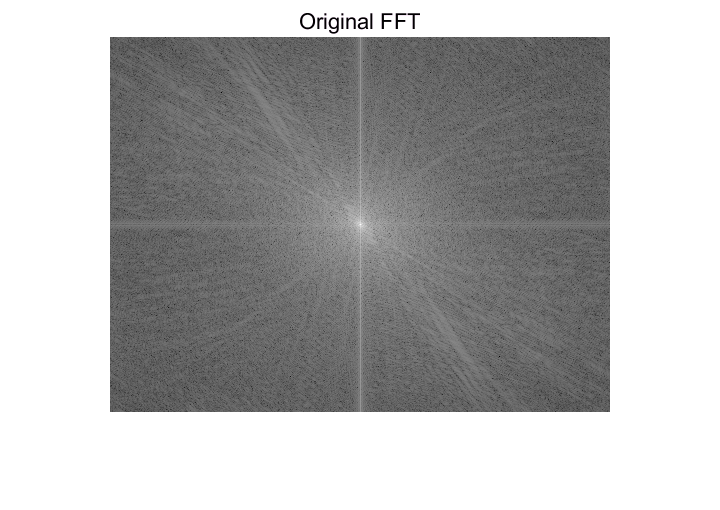


[M, N] = size(Noise);

%%% FFT %%%
Original_fft = fft2(double(Original));
Original_fft_shift = fftshift(Original_fft);
Noise_fft = fft2(double(Noise));
Noise_fft_shift = fftshift(Noise_fft);
imshow(log(abs(Original_fft_shift) + 1), []); title('Original FFT');

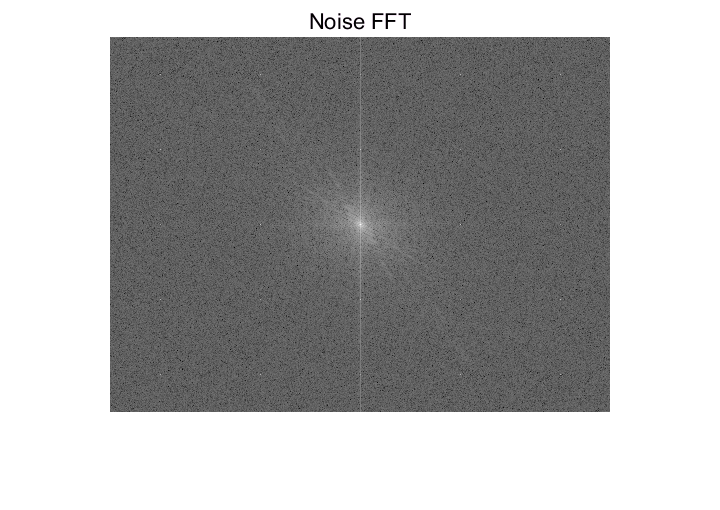

imshow(log(abs(Noise_fft_shift) + 1), []); title('Noise FFT');

%%% FFT %%%

%%% xb %%%
FreqFilter = Noise;
Filter_fft = fft2(double(FreqFilter));
Filter_fft_shift = fftshift(Filter_fft);

H = double(ones(M, N));
midx=round(M/2);
midy=round(N/2)+1;
dx=floor(M/5);
dy=floor(N/5);
row = [midx-2*dx, midx-dx, midx, midx+dx, midx+2*dx];
col = [midy-2*dy, midy-dy, midy, midy+dy, midy+2*dy];
dr = 0; dc = 0;

for i = 1:5
    for j = 1:5
        H(row(i) - dr:row(i) + dr, col(j) - dc:col(j) + dc) = 0;
    end
end

H(row(3) - dr:row(3) + dr, col(3) - dc:col(3) + dc) = 1;
Filter_fft_shift = Filter_fft_shift .* H;
Filter_fft = ifftshift(Filter_fft_shift);
FreqFilter = real(ifft2(Filter_fft));

mse_Original_Freq = immse(Original, FreqFilter)

mse_Original_Freq = 460.6043

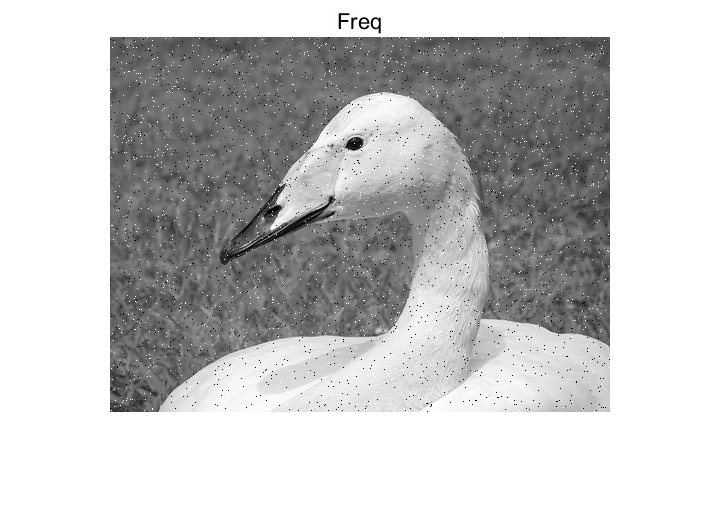

imshow(mat2gray(FreqFilter)); title('Freq');

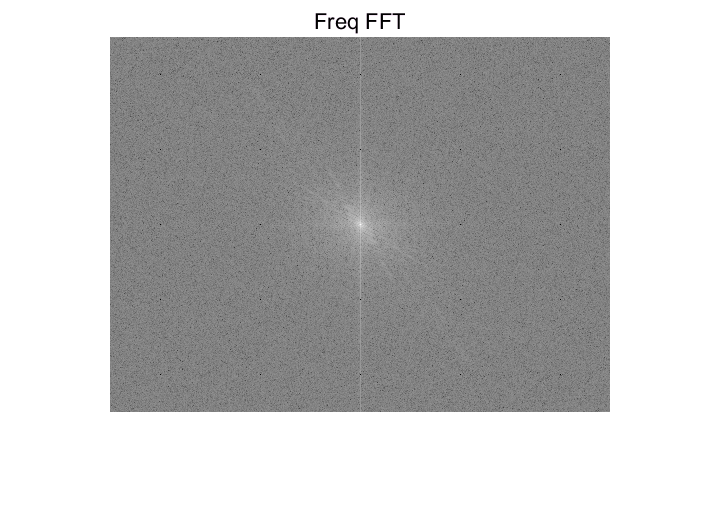

imshow(log(abs(Filter_fft_shift) + 1), []); title('Freq FFT');

%%% xb %%%

%%% Median %%%
SpatialFilter = medfilt2(FreqFilter, [3, 3], 'symmetric');
%%% Median %%%

mse_Original_Final = immse(Original, SpatialFilter)

mse_Original_Final = 208.0741

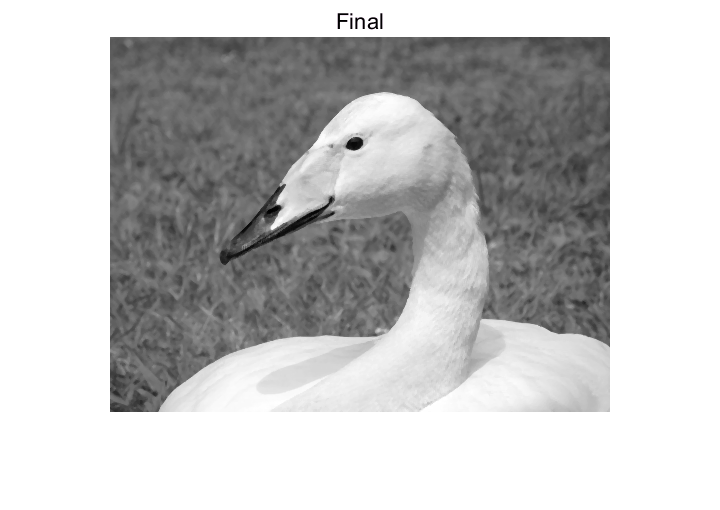

imshow(mat2gray(SpatialFilter)); title('Final');

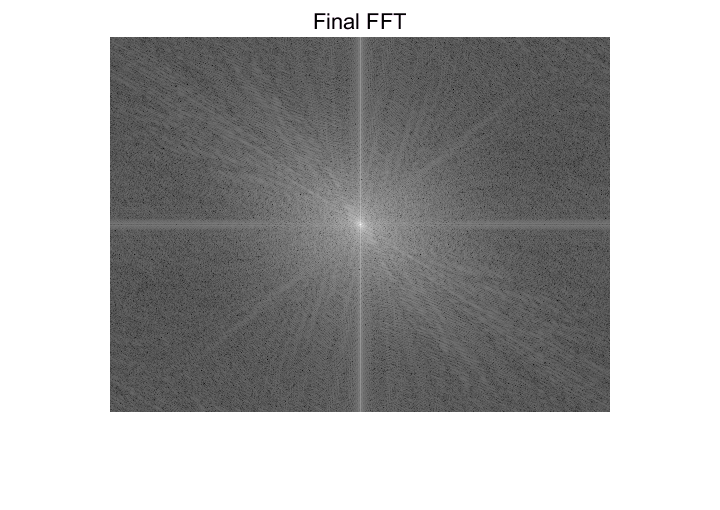

Filter_fft = fft2(SpatialFilter);
Filter_fft_shift = fftshift(Filter_fft);
imshow(log(abs(Filter_fft_shift) + 1), []); title('Final FFT');

imwrite(mat2gray(SpatialFilter),'ans.bmp')

Original_Uint = imread('swanOriginal.bmp');
Noise_Uint = imread('swanNoise.bmp');

Original = double(Original_Uint);
Noise = double(Noise_Uint);

mse_Original_Noise = immse(Original, Noise)% 原图和噪声

mse_Original_Noise = 858.7204


[M, N] = size(Noise);

%%% Median %%%
Filter = medfilt2(Noise, [3, 3], 'symmetric');
mse_Original_Median = immse(Original, Filter)

mse_Original_Median = 527.6786

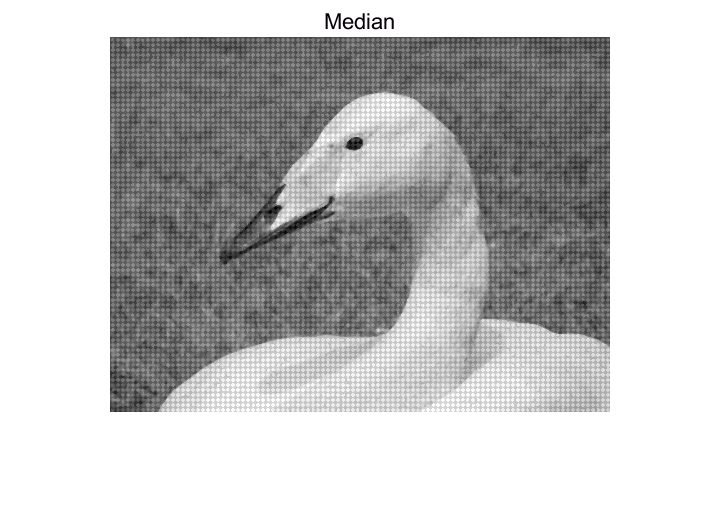

imshow(mat2gray(Filter)); title('Median');

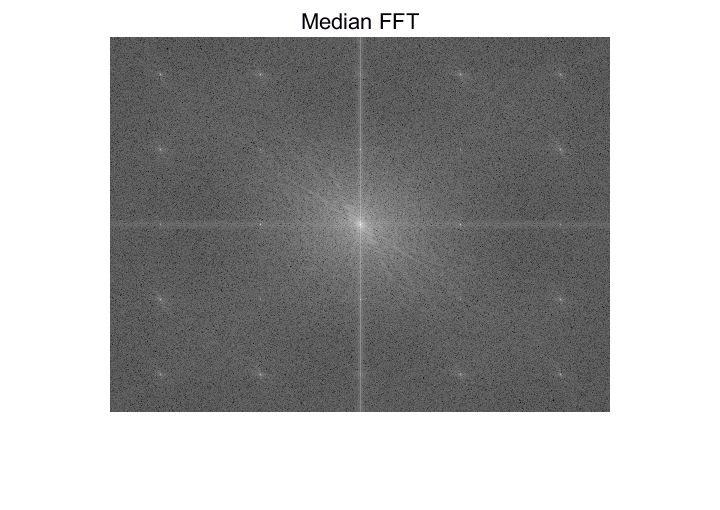

Filter_fft = fft2(Filter);
Filter_fft_shift = fftshift(Filter_fft);
imshow(log(abs(Filter_fft_shift) + 1), []); title('Median FFT');

%%% Median %%%

%%% xb %%%
Filter_fft = fft2(double(Filter));
Filter_fft_shift = fftshift(Filter_fft);

H = double(ones(M, N));
midx=round(M/2);
midy=round(N/2)+1;
dx=floor(M/5);
dy=floor(N/5);
row = [midx-2*dx, midx-dx, midx, midx+dx, midx+2*dx];
col = [midy-2*dy, midy-dy, midy, midy+dy, midy+2*dy];
dr = 0; dc = 0;

for i = 1:5
    for j = 1:5
        H(row(i) - dr:row(i) + dr, col(j) - dc:col(j) + dc) = 0;
    end
end

H(row(3) - dr:row(3) + dr, col(3) - dc:col(3) + dc) = 1;
Filter_fft_shift = Filter_fft_shift .* H;
Filter_fft = ifftshift(Filter_fft_shift);
Filter = real(ifft2(Filter_fft));

mse_Original_Final = immse(Original, Filter)

mse_Original_Final = 253.2478

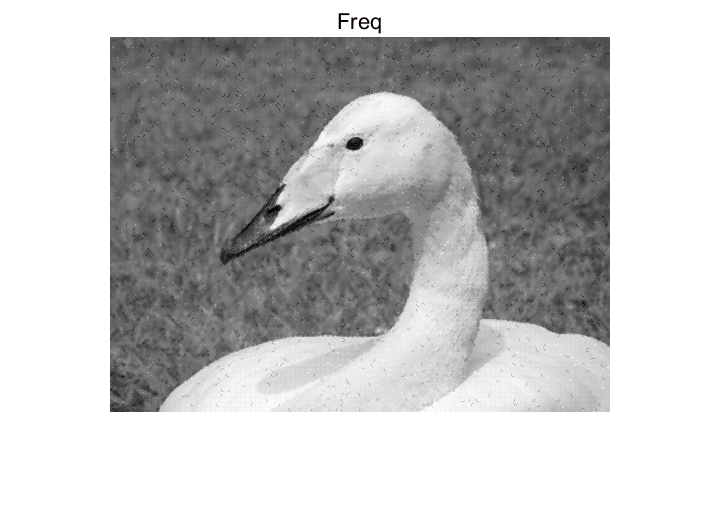

imshow(mat2gray(Filter)); title('Freq');

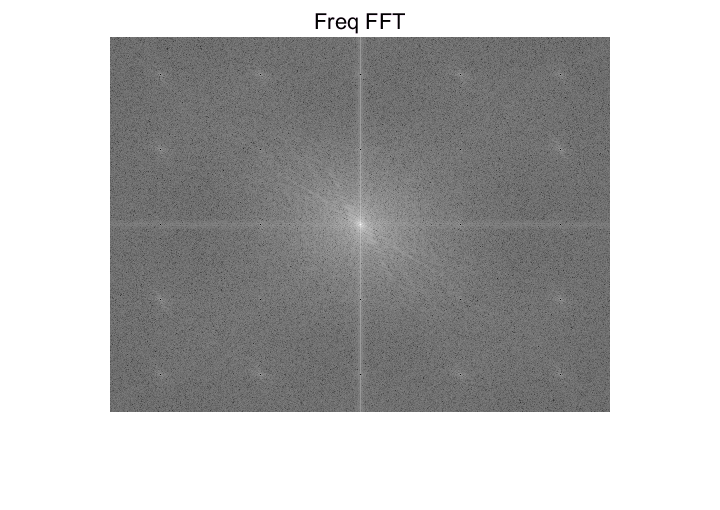

imshow(log(abs(Filter_fft_shift) + 1), []); title('Freq FFT');

%%% xb %%%

imwrite(mat2gray(Filter),'cmp.bmp')